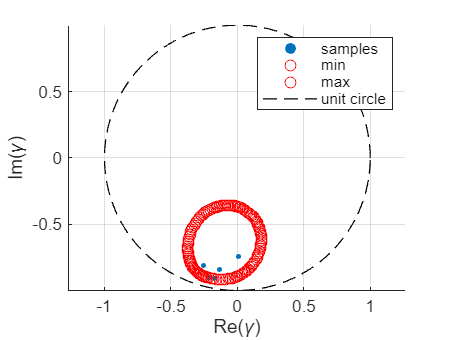

clear;

fileName = "data/c3x7_s1602_l48.m"; 
boundary_N = 60;

CoherencePoints = PauliBasesPoints(fileName);
boundary_vals = BoundaryScan(fileName, boundary_N);

% --- Plot the brute-force sampled points ---
figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(CoherencePoints), imag(CoherencePoints), 8, 'filled');

scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);

% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');


% legend
legend('samples','min','max', 'unit circle');

hold off;  % optional, release hold